# Plots

This script is for making plots to compare specific data.

## 👤 User inputs

clc; clear all;

% Specify the testbed to be evaluated
TESTBEDs = {'IBAL', 'ASHP', 'WSHP'};
TESTBED = TESTBEDs{1};

## 🚀 Initialization and load data

% Add path to the subfunctions
addpath(fullfile(pwd,'subfunc'));

% Data folder
dataFolder = fullfile(pwd,TESTBED);

% Find all 'data.csv' files under the base folder, including subfolders
files = dir(fullfile(dataFolder, '**', 'data.csv'));

% Loop through all files
for i = 1:length(files)
    
    % Read the CSV file into a table
    dataTable = readtable(fullfile(files(i).folder, files(i).name));
    
    % Construct variable name from the path
    relativePath = strrep(files(i).folder, dataFolder, ''); % Remove base path
    relativePath = strrep(relativePath, '\', '.'); % Replace file separators with dots
    if startsWith(relativePath, '.')
        relativePath = extractAfter(relativePath, 1); % Remove leading dot
    end
    
    % Use eval to dynamically create the variable in the base workspace
    evalin('base', ['allCases.' relativePath '.data = dataTable;']);
    
end

## 📊 Plots

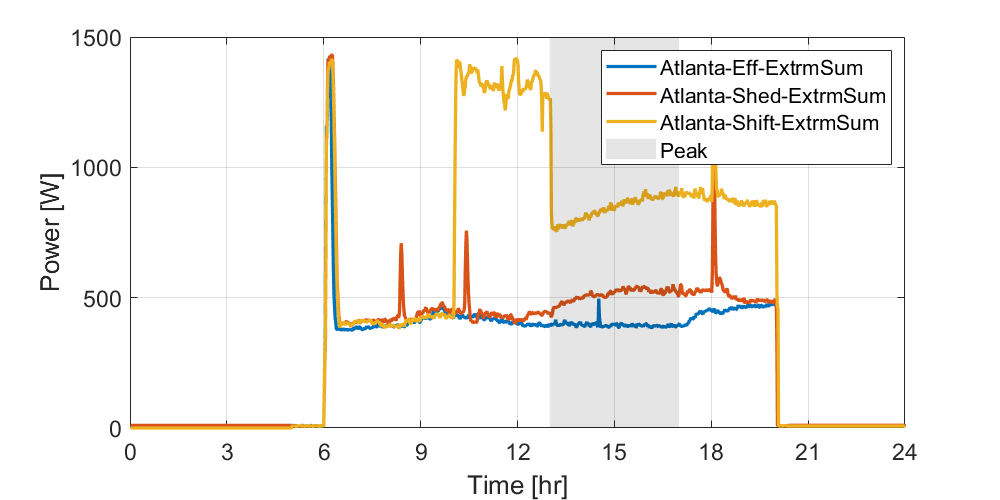

% var_name = 'wshp_power';
% var_name = 'zn_temp_sim';
var_name = 'ahu1_fan_power';

y1 = allCases.Atlanta.Eff.ExtrmSum.data.(var_name);
y2 = allCases.Atlanta.Shed.ExtrmSum.data.(var_name);
y3 = allCases.Atlanta.Shift.ExtrmSum.data.(var_name);
x1 = [1:length(y1)]/60;

figure('Position', [100, 100, 800, 400])
plot(x1, y1, 'LineWidth', 2);
hold on
plot(x1, y2, 'LineWidth', 2);
hold on
plot(x1, y3, 'LineWidth', 2);

grid on
xlim([0,24]);
xticks([0:3:24]);
xlabel("Time [hr]");
ylabel("Power [W]");
% ylabel("Temperature [F]");
set(gca, 'FontSize', 14);

% Add shaded area for peak time
ylim_curr = ylim;
fill([13 17 17 13], [ylim_curr(1) ylim_curr(1) ylim_curr(2) ylim_curr(2)], 'k', 'FaceAlpha', 0.1, 'EdgeColor', 'none');

legend("Atlanta-Eff-ExtrmSum", "Atlanta-Shed-ExtrmSum", "Atlanta-Shift-ExtrmSum", "Peak")